%% Cubic spline interpolation
hold off
clear all
close all
syms x
% nodes
X = [1, 2, 3, 4, 5, 6, 7, 8];
Y = [2, 6, 3, 8, 6, 9, 1, 9];
n = length(X);
h = diff(X);

% second derivatives M at the nodes (natural spline: M(1) = M(n) = 0)
A = zeros(n);
b = zeros(n, 1);
A(1,1) = 1

A =      1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


A(n,n) = 1

A =      1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1


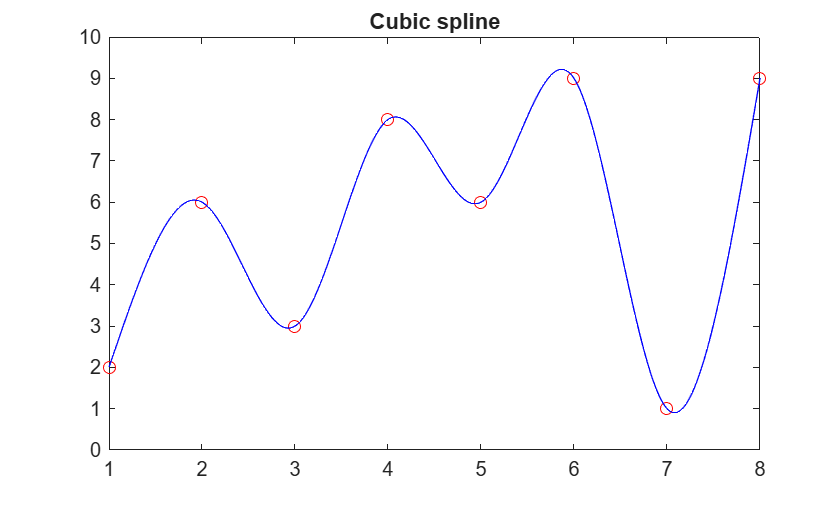

for i = 2:n-1
    A(i,i-1) = h(i-1);
    A(i,i)   = 2*(h(i-1) + h(i));
    A(i,i+1) = h(i);
    b(i) = 6*((Y(i+1)-Y(i))/h(i) - (Y(i)-Y(i-1))/h(i-1));
end
M = A \ b;

plot(X, Y, 'ro')
hold on
for i = 1:n-1
    S = M(i)  *(X(i+1)-x)^3/(6*h(i)) ...
      + M(i+1)*(x-X(i))^3  /(6*h(i)) ...
      + (Y(i)/h(i)   - M(i)  *h(i)/6)*(X(i+1)-x) ...
      + (Y(i+1)/h(i) - M(i+1)*h(i)/6)*(x-X(i));
    fplot(S, [X(i) X(i+1)], 'b')
end
title('Cubic spline')

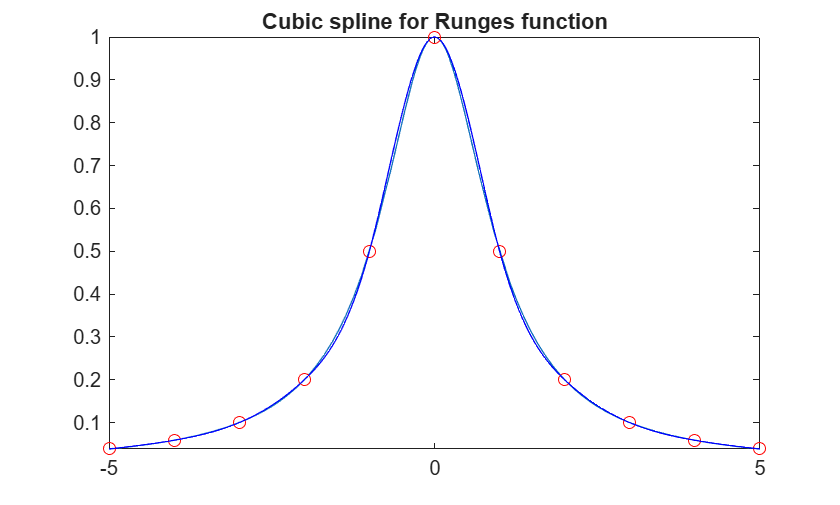


%% Runge's function
figure
R = 1 / (1+x^2);
fplot(R, [-5 5])
XR = -5:5;
YR = 1./(1+XR.^2);
n = length(XR);
h = diff(XR);

A = zeros(n);
b = zeros(n, 1);
A(1,1) = 1;
A(n,n) = 1;
for i = 2:n-1
    A(i,i-1) = h(i-1);
    A(i,i)   = 2*(h(i-1) + h(i));
    A(i,i+1) = h(i);
    b(i) = 6*((YR(i+1)-YR(i))/h(i) - (YR(i)-YR(i-1))/h(i-1));
end
M = A \ b;

hold on
plot(XR, YR, 'ro')
for i = 1:n-1
    S = M(i)  *(XR(i+1)-x)^3/(6*h(i)) ...
      + M(i+1)*(x-XR(i))^3  /(6*h(i)) ...
      + (YR(i)/h(i)   - M(i)  *h(i)/6)*(XR(i+1)-x) ...
      + (YR(i+1)/h(i) - M(i+1)*h(i)/6)*(x-XR(i));
    fplot(S, [XR(i) XR(i+1)], 'b')
end
title('Cubic spline for Runges function')